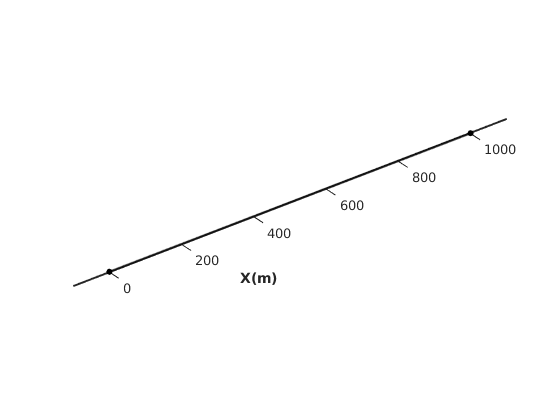

% Create a simulator object
sim = Sim();

% Disable Radar initialization, since this example uses
% a single lane on the ground
sim.en_init_radar = false;

% Define a single-lane LBSD object
lane_length_m = 1000;
num_lanes = 1;
lbsd = LBSD.genSimpleLanes(lane_length_m*ones(1,num_lanes));
sim.lbsd = lbsd;

figure;
h_lbsd = lbsd.plot();

disp(lbsd.lane_graph.Nodes)

         XData    YData    ZData    Launch    Land    Name 
         _____    _____    _____    ______    ____    _____

    1       0       0        0        1        0      {'1'}
    2    1000       0        0        0        1      {'2'}



disp(lbsd.lane_graph.Edges)

            EndNodes       Weight
         ______________    ______

    1    {'1'}    {'2'}     1000 



sim.initialize(true);

Checking if LBSD is Instantiated
Initializing ATOC


Initializing UAS Dataset
Initializing UAS Trajectories
Updating Metrics
Done
